# Auto-generated by Image Acquisition Explorer

Generated in MATLAB R2023b on 13-Mar-2024 23:36:44

## Connect to Device

Create connection to the device using the specified adaptor with the specified format.

v = videoinput("winvideo", 1, "MJPG_320x240");

## Configure Device Properties

Configure videoinput properties to prepare for acquisition.

v.ReturnedColorspace = "rgb";

## Configure File Logging

Configure the device to log video to disk. Set the desired file location and name.

filelocation = "C:\Users\krzys\Desktop\Interfejsy Multimodalne\lab1";
filename = "testVideo11.avi";
fullFilename = fullfile(filelocation, filename);

% Create and configure the video writer
logfile = VideoWriter(fullFilename, "Motion JPEG AVI");

% Configure the device to log to disk using the video writer
v.LoggingMode = "disk";
v.DiskLogger = logfile;

## Record Video for Set Number of Seconds

Record video data for a specified period of time.

numSeconds = 30;
v.FramesPerTrigger = Inf;

start(v);
pause(numSeconds);
stop(v);

% Wait for all frames to be written to disk
while v.FramesAcquired ~= v.DiskLoggerFrameCount
    pause(.1);
end

## Show Recording

View the recorded video.

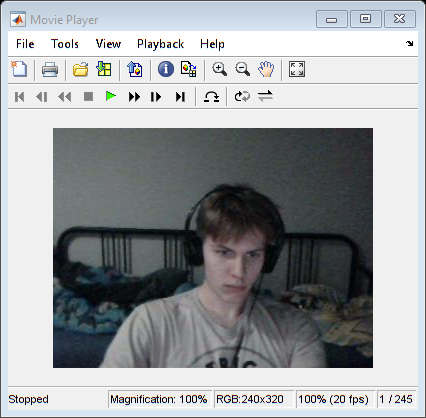

reader = VideoReader(fullFilename);
videoData = read(reader);
implay(videoData);

## Clean Up

Delete the videoinput object and clear variables from the workspace.

delete(v)

Unrecognized function or variable 'v'.

clear v

## **Rezultaty**

## **III **

Live Script na górze

parametry:

Frame Rate: 30

## IV

FPS = 11.3718

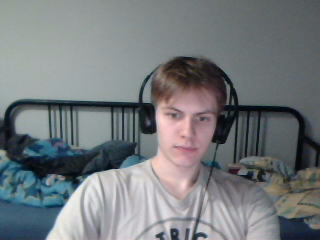

## VI

fh = figure;
ile_ramek = 10;
elapsedTime=zeros(1,ile_ramek);
for i = 1:ile_ramek
 tic
 IM = imread('http://149.156.124.49/axis-cgi/jpg/image.cgi');
 elapsedTime(1, i) = toc;

 imshow(IM);
 title(['ramka nr ' num2str(i)])
 drawnow
end
disp(['FPS = ' num2str(1/mean(elapsedTime))])


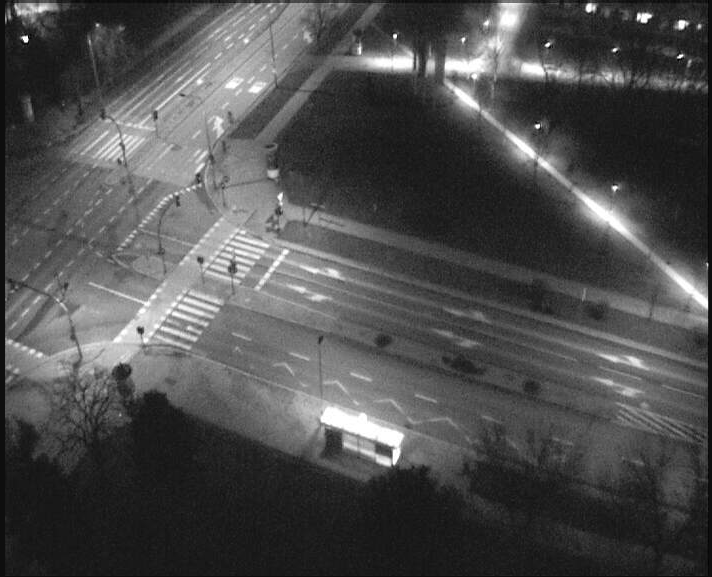

FPS = 4.4097

## Analiza i Wnioski

## **III**

- czas akwizycji jednej ramki to ogólnie 1/FPS w tym przypadku: 1/30 sekundy

- teoretyczny rozmiar to 30 * 30 * 320 * 240 * 3 byteów ( 30 sekund, 30 FPS, rozdzielczość 320x240, obraz rgb 3byte na pixel) co daje 207 360 000 byte, faktyczny romiar to 3 074 724 bytes dlatego, że jedyną opcją odczytu na moim sprzęcie było MJPG 320x240

## V

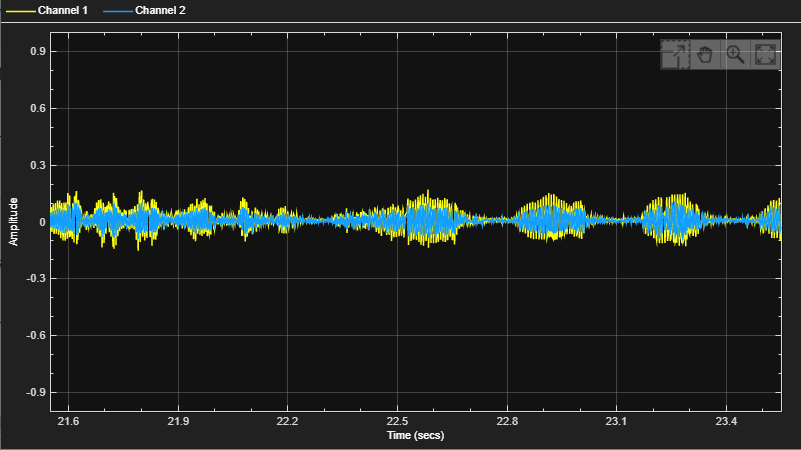

#### Jeżeli nie nadąża odczyt jest opóźniony lub traci część informacji.

## Pytania

**I**

- Istotny jest narzędzie imtool, które pozwala na dogłędną analize struktóry obrazu

- Całe narzędzie ImageAcquisitionExplorer, które umożliwia przyjemne operowanie kamerą i obrazem

- audioDeviceReader umożliwia konfigurację odczytu danych na wiele sposobów

**II**

- bezpośrednie odczytywanie obrazu z kamer na żywo poprzez dane z serwera

- analiza schematu odbieranych dźwięków

**III**

- do czego służy obiekt przetwarzania sygnały (reverberator)